# Minimum Fuel to Climb Path

% The purpose of this project is to optimize the climb path to 
% a required Mach number and altitude to minimize fuel consumption.
% This will utilize given aircraft and engine performance parameters

## User Input

M_f = 1.5; %unitless
Alt_f = 30000; % ft
step = 10; % seconds

## Constants

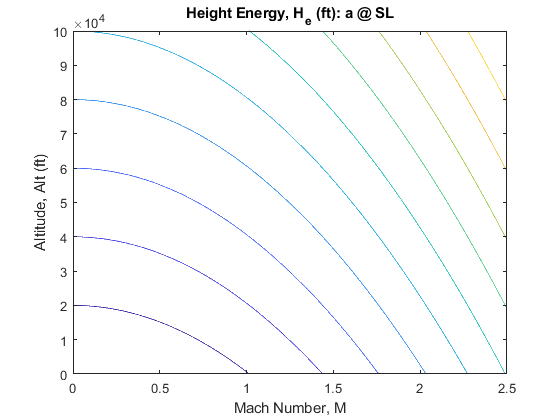

g = 32.2; % ft/s^2
M_vect = linspace(0,2.5,251); % unitless
Alt_vect = linspace(0,100,1001)'*1000;
[~, a_SI, ~, ~] = atmosisa(0); % SL (0) instead of Alt_vect;
a_vect = convvel(a_SI,'m/s','ft/s')';
%[M_mat, a_mat] = meshgrid(M_vect, a_vect);
V_mat = M_mat.*a_vect;%V_mat = M_mat.*a_mat;

%H_e = h+v^2/(2*g); % ft, height energy
[M_mat, Alt_mat] = meshgrid(M_vect, Alt_vect);
H_mat = Alt_mat+(V_mat.^2)./(2*g);
figure(1)
contour(M_mat,Alt_mat,H_mat)
xlabel('Mach Number, M')
ylabel('Altitude, Alt (ft)')
title('Height Energy, H_e (ft): a @ SL')


%C_L = 
